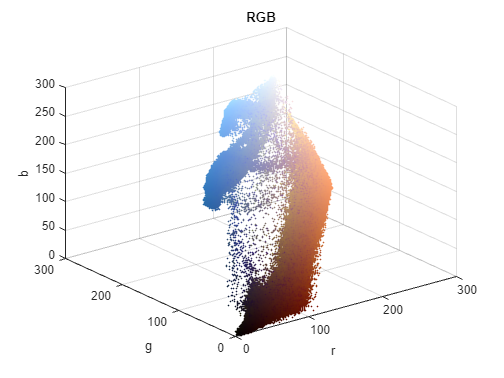

% a)
pic = imread("archesrgbklein.png");
% b)
figure;
list_rgb = reshape(pic,[],3);
color = double(list_rgb)./255;
scatter3(list_rgb(:,1), list_rgb(:,2), list_rgb(:,3), 1, color)
xlabel("r");
ylabel("g");
zlabel("b");
title("RGB");

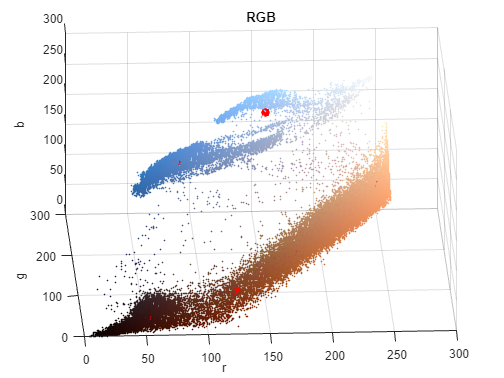


small_pic = imresize(pic, 0.4, "nearest"); 
small_list_rgb = reshape(small_pic,[],3);
color = double(small_list_rgb)./255;
scatter3(small_list_rgb(:,1), small_list_rgb(:,2), small_list_rgb(:,3), 1, color)
xlabel("r");
ylabel("g");
zlabel("b");
title("RGB");

% c)
small_pic = imresize(pic, 0.2, "nearest"); 
small_list_rgb = double(reshape(small_pic,[],3));

k = 8;
[idx, centers] = kmeans(small_list_rgb, k, 'distance', 'sqEuclidean', 'Replicates', 3);
hold on;
scatter3(centers(:, 1), centers(:, 2), centers(:, 3), 'r*', 'LineWidth', 5);
hold off;